# PT1-Strecke (DC-Motor) mit P-Regler

Aufgaben Ziel der Übung ist es, eine Führungsgrößenregelung für eine Drehzahlregelung eines Gleichstrommotors mit Simulink zu simulieren und zu untersuchen.

clear, close all, clc

s = tf('s'); % erstellen der komplexen Frequenz

## Modellierung der Motor-Regelstrecke

Es soll der DC-Motor von hps-Systemtechnik (siehe Laborübung) als PT1-Strecke modelliert werden (Eingang: Motorspannung, Ausgang: Tachogenerator; Ks=500,T1=55ms).

- Übertragungsfunktion Gs(s) der Strecke erstellen

- Sprungantwort darstellen

- Frequenzgang darstellen

%<ToDo />
Ks = 1.6; %Übertragungsbeiwert
T1 = 55e-3; %Zeitverzögerung
Gs = Ks/(1+s*T1) %Übertragungsfunktion


Gs =
 
      1.6
  -----------
  0.055 s + 1
 
Continuous-time transfer function.



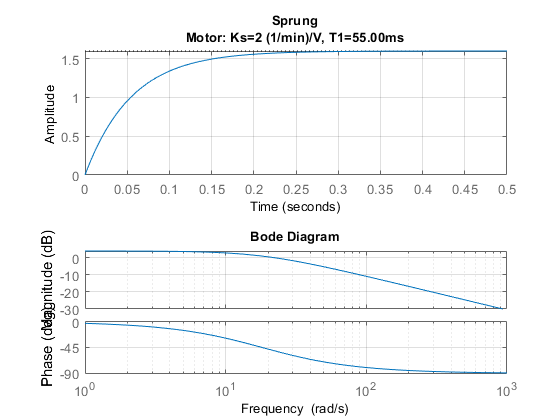


cMotor = sprintf('Motor: Ks=%.0f (1/min)/V, T1=%.2fms', [Ks, T1*1e3]);
figure,
subplot(211), step(Gs), grid on, title({'Sprung', cMotor})
subplot(212), bode(Gs), grid on

## Offenen Regelkreis G0(s) vs. Geschlossener Regelkreis Gw(s)

Es soll die Sprungantwort und der Frequenzgang des offenen Regelkreises (Schleifenverstärkung), sowie des geschlossenen Regelkreises (Führungsgrößenübertragungsfunktion) für zwei Einstellungen des P-Reglers (Kp={1, 50} untersucht werden. 

Werden Strecken mit Ausgleich mit einem P-Regler geregelt, so verbleibt stets eine bleibende Regelabweichung. Diese kann aus der Schleifenverstärkung bei der Frequenz Null (d.h. für Gleichgrößen K0=G0(0) ) berechnen werden - dies ist nur für Strecken mit Ausgleich in Kombination mit P-Reglern sinnvoll!

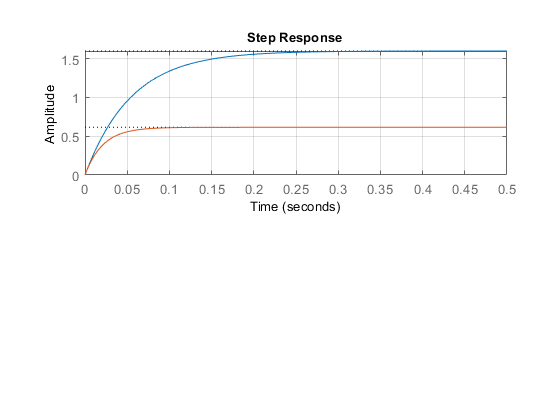

%<ToDo />
Kp = 1;
Gr = Kp*s^0;
G0 = Gr * Gs;
Gw = G0 / (1+G0);
Gw = feedback(G0, 1);

dw = 1;
K0 = Kp * Ks;
Kw = K0/(1+K0);

Tw = T1/(1+K0);

x_stat = Kw *dw;

figure,
subplot(211), step(Gs, Gw), grid on

## Führungsgrößenübertragungsfunktion Gw(s)

Leiten sie den Führungsgrößenübertragungsfunktion Gw(s) für einen geschlossenen Regelkreis mit einer PT1-Strecke und einem P-Regler allgemein her. Analysieren sie die resultierenden Übertragungsfunktion und charakterisieren sie diese. Berechnen Sie die charakterisitischen Größen der resultierenden Übertragungsfunktion.

%<ToDo />

## Geschlossener Regelkreis (Stellgrößenverhalten)

Untersuchen sie nun das Verhalten der Stellgröße. Verwenden sie dazu das pidtool().

%<ToDo />